datos1 = readmatrix('usort_PI.xlsx');
datos2 = readmatrix('usort_PI.xlsx','Range','A1810:D3842');

t = datos1(:,1);
r = datos1(:,2);
y = datos1(:,3)

y =    20.1184
   19.9143
   20.0674
   20.1184
   19.8633
   19.9143
   19.8123
   20.1184
   19.9653
   19.9653


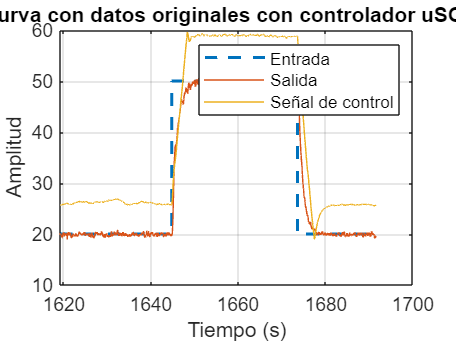

u = datos1(:,4);

figure(1)
plot(t, r,'--', LineWidth=1.5)
hold on
plot(t, y, t, u);
title('Curva con datos originales con controlador uSORT')
legend('Entrada', 'Salida', 'Señal de control')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off


t2 = datos2(:,1);
r2 = datos2(:,2);
y2 = datos2(:,3)

y2 =    19.8633
   19.7102
   19.7612
   19.7102
   19.7102
   19.7102
   19.9653
   19.9143
   20.0164
   20.0164


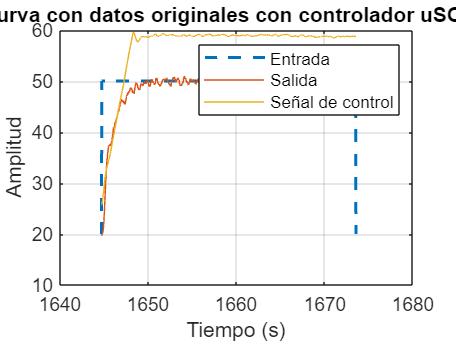

u2 = datos2(:,4);

figure(2)
plot(t2, r2,'--', LineWidth=1.5)
hold on
plot(t2, y2, t2, u2);
title('Curva con datos originales con controlador uSORT')
legend('Entrada', 'Salida', 'Señal de control')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

# Sobrepaso máximo porcentual

yf = mean(y(2241:3503))

yf = 49.9998

Ymax = max(abs(max(y)),abs(min(y)))

Ymax = 51.1940

Ymax = max(y)

Ymax = 51.1940


Mpn = (abs(max(y)-yf)/yf)*100

Mpn = 2.3884

# Tiempo de asentamiento al 2%

ind = find(y>max(y)-0.02*(max(y)),1)-1

ind = 2178

ta2 = t(ind) -1644.74

ta2 = 5.1687

# Error permanente

epr0 = mean(abs(r-y))

epr0 = 1.1833

epr0 = mean(abs(r2-y2))

epr0 = 1.5077

# IAE

IAE1 = trapz(t,abs(r-y))

IAE1 = 86.1909

IAE2 = 43.3318

IAE2 = trapz(t2,abs(r2-y2))

# Esfuerzo de control maximo

Umax = max(abs(1-max(u)),abs(1-min(u)))

Umax = 58.6007